# **TDSÑ: Práctica 1**

Antes de comenzar ejecute el siguiente código para borrar las variables del espacio de trabajo, añadir el *toolbox* del laboratorio, establecer un tamaño de gráfica por defecto y eliminar algunos avisos del editor.

clear, subplot
addpath('tdsbox')
dfp = get(groot, 'DefaultFigurePosition');
set(groot, 'DefaultFigurePosition', [0, 0, 500, 300])
%#ok<*NASGU>
%#ok<*ASGLU>

## **Instrucciones**

- *Escriba las direcciones de los correo-e suya y de su pareja en las variables *`alumno_1`* y *`alumno_2`* y ejecute la sección.*

- *La práctica incluye varias tareas que debe contestar en este mismo archivo en las zonas marcadas desde *`% SU CÓDIGO AQUÍ`* hasta *`% --------------.`

- *No cambie las llamadas a la función *`check_task`.

- *Cuando termine las tareas guarde este archivo y súbalo a la carpeta de entrega de Moodle. No cambie el nombre ni el tipo de archivo.*

alumno_1 = 'ignacio.aguirrec@alumnos.upm.es';
alumno_2 = 'ines.valdivielso@alumnos.upm.es';
check_task(100, 'es');

>>>>> [1:0:0] Correcto.


## 1. Señales discretas y vectores

La palabra MATLAB es un acrónimo de ***mat****rix ****lab****oratory* (laboratorio de matrices) y hace referencia a la capacidad de este lenguaje para trabajar con matrices (o vectores) de forma sencilla y eficiente.

En MATLAB las señales se almacenan en vectores unidimensionales, preferiblemente de tipo columna. Por defecto, los vectores están compuestos por elementos en punto flotante (reales o complejos) con doble precisión (64 bits equivalentes a unos 15 dígitos decimales de precisión).

Los números complejos deben escribirse usando la unidad imaginaria `1j`. Por ejemplo, 

3 + 1j

ans = 3.0000 + 1.0000i

-3.5j

ans = -0.0000 - 3.5000i

Si necesita combinar las partes real e imaginaria use la función [`complex`](matlab: doc complex)

a = 2.5

a = 2.5000

b = -1.3

b = -1.3000

complex(a, b)

ans = 2.5000 - 1.3000i

o una expresión como

a + b*1j

ans = 2.5000 - 1.3000i

Para convertir un vector fila en un vector columna (o viceversa) se usa el operador transposición: `'` (comilla simple). Por ejemplo, el vector `x` siguiente contiene 4 elementos con valores $2$, $3$, $-1$ y $3.5$.

x = [2, 3, -1, 3.5]'

x =     2.0000
    3.0000
   -1.0000
    3.5000


Pero la operación de transposición aplica además conjugación compleja. Si el vector contiene valores complejos y no se requiere conjugación puede usar la función [`transpose`](matlab: doc transpose) o el operador comilla precedido de un punto, como si se tratara de aplicar el operador elemento a elemento:

y = [1+2j, 1, 0.3*exp(-1j*pi/5)].'

y =    1.0000 + 2.0000i
   1.0000 + 0.0000i
   0.2427 - 0.1763i


En MATLAB los elementos de un vector se indexan con una *expresión de índice* entre paréntesis; por ejemplo el primer elemento del vector `x` es `x(1)`, el tercero `x(3)`, y los dos últimos `x(end-1:end)` usando la palabra clave `end` que indica el último elemento.

x(1)

ans = 2

x(3)

ans = -1

x(end-1:end)

ans =    -1.0000
    3.5000


Los índices solo pueden tomar valores enteros positivos en el rango desde 1 a la longitud del vector. Las expresiones `x(0)` o `x(length(x)+1)` producirán un error.

#### **Tarea 1.1.1**

Cree el vector columna `x` con los valores $1+\mathrm{j}$, $1-\mathrm{j}$, $-4$, $2$, $2\mathrm{j}$ y $-3.5\mathrm{j}$.

% SU CÓDIGO AQUÍ
x = [1 + 1i; 1-1i; -4; 2; 2j; -3.5j ]

x =    1.0000 + 1.0000i
   1.0000 - 1.0000i
  -4.0000 + 0.0000i
   2.0000 + 0.0000i
   0.0000 + 2.0000i
   0.0000 - 3.5000i


% --------------
check_task(111, 'es');

>>>>> [1:1:1] Correcto.


Es frecuente confundir el manejo de vectores con el manejo de las señales discretas ya que ambos se indexan con valores enteros. Los vectores son de longitud finita por lo que solo pueden contener un trozo de una señal. Además el trozo puede comenzar en cualquier muestra de la señal. Por ejemplo, el vector:

`x = [0, 0, 0, 1, 1, 1, 1]'`

contiene 7 muestras de la señal $x[n]=u[n]$ a partir de $\(n=-3\)$. Así pues, para indexar el elemento correspondiente a $n=0$ debe usarse `x(4)` porque esta muestra se encuentra en el cuarto elemento del vector; si se intenta acceder a esta muestra con `x(0)` se producirá un error porque en un vector no existe tal elemento. No debe confundirse, por tanto, el índice temporal $\(n\)$ de la señal con los índices de los vectores.

Nótese, además, que el vector `x` anterior contiene la señal $x[n]=u[n]$ en el intervalo $-3 \le n \le 3 $, pero también puede representar cualquier otra señal discreta que comparta con $x[n]$ las mismas muestras; por ejemplo, $y[n]=u[n-3],\ 0\le n\le6$. Es decir, un vector no identifica de forma unívoca a una señal discreta.

#### **Tarea 1.1.2**

Cree el vector columna `z` con 4 muestras de la señal $z[n]=\delta[n-1]$ en el intervalo $-1\le n \le 2$.

% SU CÓDIGO AQUÍ
n = -1:2;
z = [ 0; 0; 1; 0]

z =      0
     0
     1
     0


% --------------
check_task(112, 'es');

>>>>> [1:1:2] Correcto.


Las señales discretas deben dibujarse con la función [`stem`](matlab: doc stem), indicando el rango de índices y los valores de la señal. La señal $x[n]=\delta[n] -2 \delta[n-1]$ en el intervalo $-1 \le n \le 2$ se dibuja con

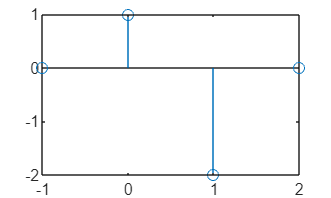

n = -1:2;
x = [0, 1, -2, 0];
stem(n, x)

La apariencia puede mejorarse con algunos ajustes y decoraciones

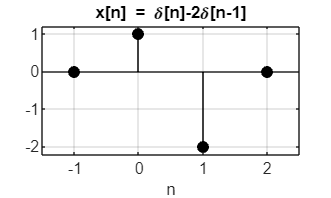

stem(n, x, 'k', 'filled')
title('x[n] = \delta[n]-2\delta[n-1]')
xlabel('n'), axis([-1.5, 2.5, -2.2, 1.2]), grid on

La representación con la función [`plot`](matlab: doc plot) debe reservarse para señales o funciones continuas o señales discretas con muchas muestras. Por omisión, el intervalo de una señal con $L$ elementos debe ser $0 \le n \le L-1$.

x = randn(1000, 1);
plot(0:numel(x)-1, x);
title('Señal aleatoria')
xlabel('n'), grid on

#### **Tarea 1.1.3**

Genere y dibuje la señal $z[n]=u[n+1]$ en el intervalo $-2 \le n \le 2$.

clf
% SU CÓDIGO AQUÍ
n = -2:2;
u = [0;1;1;1;1]

u =      0
     1
     1
     1
     1


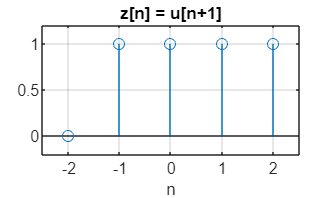

stem(n,u);
% --------------
title('z[n] = u[n+1]')
xlabel('n'), axis([-2.5, 2.5, -0.2, 1.2]), grid on

check_task(113, 'es');

>>>>> [1:1:3] Correcto.


Las señales pueden importarse desde archivos. Cuando los archivos son de tipo MATLAB (extensión `.mat`) la señal puede leerse con la función [`load`](matlab: doc load). El archivo puede contener además de la señal la frecuencia de muestreo u otras variables.

load('handel.mat')  % señal en y, frecuencia de muestreo en Fs
Fs

Fs = 8192

plot(0:numel(y)-1, y)
title('Señal "Handel"')
xlabel('n'), axis tight, grid on

También se pueden importar archivos de audio con formatos estándar (extensiones `.wav`, `.ogg`, `.flac`, `.au`, `.aif`...) con la función [`audioread`](matlab: doc audioread)

[x, fs] = audioread('speech.wav');
plot(0:numel(x)-1, x)
title('Señal "speech"')
xlabel('n'), axis tight, grid on

Si las señales son multicanal, la variable `x` es una matriz con una columna por canal.

#### **Tarea 1.1.4**

Importe la señal de audio `guitar.wav` y asigne a la variable `chan_2` el segundo canal. Recuerde que puede seleccionar la columna `c` de una matriz `A` con `A(:, c)`.

% SU CÓDIGO AQUÍ
[x, fs] = audioread('guitar.wav');
chan_2 = x(:, 2); 
% --------------
check_task(114, 'es');

>>>>> [1:1:4] Correcto.


## 2. Generación de señales discretas

La generación de señales discretas a partir de expresiones matemáticas sigue siempre el siguiente procedimiento:

- Generar el vector de índices (eje de tiempo) usando el operador '`:`'. Por ejemplo, $-3\le n\le5$ se genera con `n = -3:5`. Suele ser útil crear los índices como vector columna `n = (-3:5)'`.

- Aplicar la expresión matemática usando el vector de índices para generar un vector columna con los valores de la señal en el intervalo. Por ejemplo, la señal $x[n] = 2n + 1$ en el intervalo anterior se genera con `x = 2*n' + 1`.

#### **Tarea 1.2.1**

Genere la señal $x[n] = \frac{1}{2}\cos\left(\frac{\pi}{3} n + \frac{\pi}{4}\right)$ en el intervalo $0 \le n \le 9$.

% SU CÓDIGO AQUÍ
n = 0:9;
x = 1/2*cos((pi/3)*n + pi/4)';
% --------------
check_task(121, 'es');

>>>>> [1:2:1] Correcto.


Para generar impulsos $\delta[n]$ y escalones $u[n]$ la expresión matemática puede calcularse mediante una operación relacional y convirtiendo el resultado lógico a tipo doble. Por ejemplo,


$$\delta[n-1]=\begin{cases} 1, & n=1\\ 0, & \text{{resto}} \end{cases}$$


en el intervalo $-2 \le n \le 2$ puede calcularse con

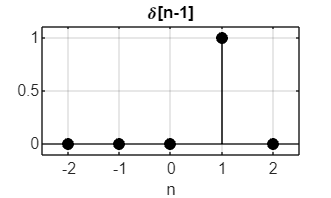

n = (-2:2)';
dm1 = double(n == 1);
stem(n, dm1, 'k', 'filled')
xlabel('n'), title('\delta[n-1]'), grid on
axis([-2.5, 2.5, -0.1, 1.1])

#### **Tarea 1.2.2**

Genere y dibuje la señal $y[n] = 2u[n+1]$ en el intervalo $-2 \le n \le 2$. Recuerde que

$u[n-1]=\begin{cases} 1, & n\ge-1\\ 0, & \text{{resto}} \end{cases}$.

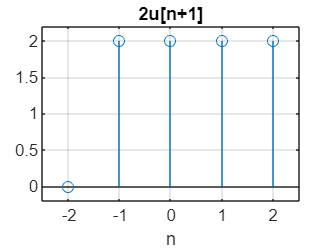

% SU CÓDIGO AQUÍ
n = (-2:2)';
y = 2*double(n>=-1);
stem(n,y)
% --------------
xlabel('n'), title('2u[n+1]'), grid on
axis([-2.5, 2.5, -0.2, 2.2])

check_task(122, 'es');

Unrecognized function or variable 'check_task'.

MATLAB trabaja de forma nativa con números complejos haciendo las oportunas conversiones cuando es necesario. Para crear una exponencial compleja basta con usar la función [`exp`](matlab: doc exp) con el argumento deseado. Por ejemplo, la señal $z[n] = \mathrm{e}^{\,\mathrm{j}0.3n}$ en el intervalo $0 \le n \le 15$ se calcula con

n = (0:15)';
z = exp(1j*0.3*n);

Nótese que por motivos de precision numérica siempre debe usarse la función [`exp`](matlab: doc exp) y no el número $\mathrm{e}$ directamente.

Para dibujar correctamente un vector complejo hay que representar por separado las partes real e imaginaria

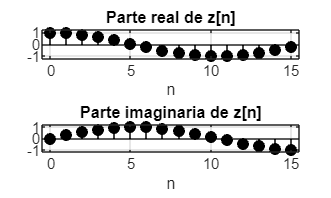

subplot(211)
stem(n, real(z), 'k', 'filled')
xlabel('n'), grid on
title('Parte real de z[n]')
axis([-0.5, 15.5, -1.2, 1.2])
subplot(212)
stem(n, imag(z), 'k', 'filled')
xlabel('n'), grid on
title('Parte imaginaria de z[n]')
axis([-0.5, 15.5, -1.2, 1.2])

#### **Tarea 1.2.3**

Genere y dibuje la señal $r[n] = 5\mathrm{e}^{-\mathrm{j}\left(\frac{\pi}{4}n+\frac{\pi}{3}\right)}$ en el intervalo $0 \le n \le 12$.

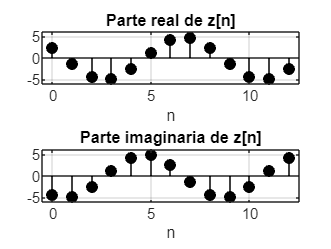

clf
% SU CÓDIGO AQUÍ
n = (0:12)';
r = 5*exp(-j*(pi/4*n+pi/3));
% --------------
subplot(211)
% SU CÓDIGO AQUÍ
stem(n, real(r), 'k', 'filled')
% --------------
xlabel('n'), grid on
title('Parte real de z[n]')
axis([-0.5, 12.5, -6, 6])
subplot(212)
% SU CÓDIGO AQUÍ
stem(n, imag(r), 'k', 'filled')
% --------------
xlabel('n'), grid on
title('Parte imaginaria de z[n]')
axis([-0.5, 12.5, -6, 6])

subplot
check_task(123, 'es');

Unrecognized function or variable 'check_task'.

Algunas expresiones requieren el uso de operadores precedidos de un punto que indican que la operación debe hacerse elemento a elemento. Por ejemplo, en la señal exponencial con base real $v[n] = \left(\frac{3}{4}\right)^n$ en el intervalo $-2 \le n \le 5$.

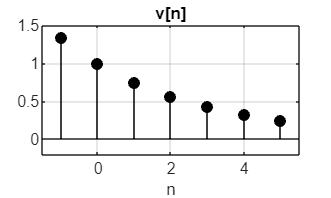

n = (-2:5)';
v = (3/4).^n;   % .^ en lugar de ^
stem(n, v, 'k', 'filled')
xlabel('n'), title('v[n]'), grid on
axis([-1.5, 5.5, -0.2, 1.5])

o cuando se combinan señales mediante multiplicación, división o exponenciación. Por ejemplo, la señal $w[n]=v[n]u[n]$ se construye con

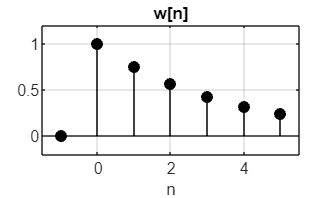

u = double(n >= 0);
w = v.*u;   % .* en lugar de *
stem(n, w, 'k', 'filled')
xlabel('n'), title('w[n]'), grid on
axis([-1.5, 5.5, -0.2, 1.2])

Cuando se combinan señales es imprescindible que todas estén definidas en el mismo intervalo y que, por tanto, los vectores tengan la misma longitud.

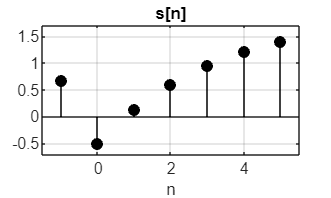

s = 0.5*v + 2*u - 3*w;
stem(n, s, 'k', 'filled')
xlabel('n'), title('s[n]'), grid on
axis([-1.5, 5.5, -0.7, 1.7])

#### **Tarea 1.2.4**

Genere y dibuje la señal $a[n] = 2^{-n}\cos\left(\frac{\pi}{3}n + \frac{\pi}{8}\right)u[n]$ en el intervalo $-2 \le n \le 8$.

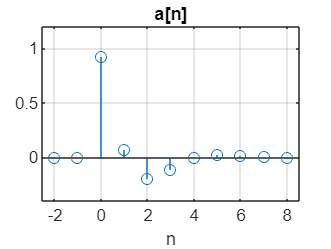

clf
% SU CÓDIGO AQUÍ
n = (-2:8)';
u = double(n>=0);
a = 2.^(-n).*cos(pi*n/3+pi/8).*u;
stem(n,a)
% --------------
xlabel('n'), title('a[n]'), grid on
axis([-2.5, 8.5, -0.4, 1.2])

check_task(124, 'es');

Unrecognized function or variable 'check_task'.

## 3. Caracterización de señales

Una función muy útil para hacer procesado de señales con MATLAB es [`sum`](matlab: doc sum). Su cometido es sumar los elementos de un vector, lo que la convierte en una herramienta idónea para calcular sumatorios, como los que aparecen, por ejemplo, en las definiciones del valor medio, la energía y la potencia de una señal.

El valor medio de una señal $x[n]$ se define como


$$\mu_x = \lim_{N\rightarrow\infty} \frac{1}{2N+1} \sum_{n=-N}^{N}x[n]$$


la energía como


$$E_x = \lim_{N\rightarrow\infty} \sum_{n=-N}^{N}\left|x[n]\right|^2$$


y la potencia media como


$$P_x = \lim_{N\rightarrow\infty} \frac{1}{2N+1} \sum_{n=-N}^{N}\left|x[n]\right|^2=\frac{1}{2N+1} E_x$$


suponiendo que los límites correspondientes existen. La existencia de límite puede ser problemática para las señales de duración infinita, pero no lo es para las señales de duración finita si todas las muestras sean finitas.

En general, se considera que las señales son de duración finita; es decir, idénticamente nulas fuera del intervalo especificado. En este caso el sumatorio puede restringirse a las muestras contenidas en los vectores de señal sin necesidad de calcular el límite.

Para calcular el valor medio se suman los valores de la señal y se dividen por su longitud.

n = (0:99)';
x = cos(pi*n/3);
mu_x = sum(x)/length(x)

El mismo resultado se puede obtener con la función [`mean`](matlab: doc mean).

El cálculo de la energía es también muy sencillo.

E_x = sum(abs(x).^2)

Otra forma de calcular la energía resulta de la igualdad $\left| x \right|^2 = x\cdot x^*$, en la que $x^*$ expresa el conjugado de $x$.

E_x = sum(x.*x)

Una tercera forma, muy eficiente, es aprovechar la vectorización y calcular el producto escalar del vector de señal $\left| x \right|^2 = <x, x^*>$.

E_x = x'*x

Nótese que el producto escalar requiere que el primer vector sea fila y el segundo columna y que la suma está implícita en el cálculo del producto.

#### **Tarea 1.3.1**

Genere la señal compleja $b[n] = \mathrm{e}^{\,\mathrm{j}\frac{\pi}{4}n}$ en el intervalo $0 \le n \le 99$ y calcule su valor medio `mu_b`.

% SU CÓDIGO AQUÍ
n = (0:99)';
b = exp(j*pi/4*n);
mu_b = mean(b);
% --------------
check_task(131, 'es');

#### **Tarea 1.3.2**

Genere la señal compleja $c[n] = 2\mathrm{e}^{-\mathrm{j}\frac{\pi}{3}n}$ en el intervalo $0 \le n \le 99$ y calcule su energía `E_c`.

% SU CÓDIGO AQUÍ
n = (0:99)';
c = 2 * exp(-j*pi/3*n);
E_c = c'*c;
% --------------
check_task(132, 'es');

#### **Tarea 1.3.3**

Genere la señal compleja $d[n] = \delta[n] + 3\mathrm{j}\cos\left(\frac{\pi}{8}n\right)u[n]$ en el intervalo $-10 \le n \le 20$ y calcule su potencia media `P_d`.

% SU CÓDIGO AQUÍ
n=(-10:20)';
d = delta + 3j*cos(pi/8*n)*u;
delta = double(n==0);
u = double(n >= 0);
% --------------
check_task(133, 'es');

Otras características de una señal pueden requerir el uso de otras funciones, por ejemplo el valor máximo y mínimo (funciones [`max`](matlab: doc max) y [`min`](matlab: doc min))

n = (0:99)';
x = 0.3*cos(pi*n/3);
max_x = max(x)
min_x = min(x)

#### **Tarea 1.3.4**

Genere la señal $e[n] =\sqrt{2}\sin\left(\frac{3\pi}{5}n\right)$ en el intervalo $0 \le n \le 25$ y calcule su valor pico a pico `Vpp_e`.

% SU CÓDIGO AQUÍ
n=(0:25)';
e = (2^(1/2) * sin(pi*(3/5) * n));
Vpp_e = max(e) - min(e);
% --------------
check_task(134, 'es');

## 4. Transformada de Fourier

La transformada de Fourier es una función compleja de variable real continua $\omega$. Se puede calcular como cualquier otra expresión usando un paso entre valores de la variable pequeño. La transformada de la señal $x[n]=\left(\frac{1}{2}\right)^n u[n]$ es $X(\omega) = \frac{1}{1-\frac{1}{2}\mathrm{e}^{-\mathrm{j}\omega}}$. Puede calcularse en el intervalo $0\le\omega\lt\pi$ y asignarse al vector columna `X` con

N = 512;
w = linspace(-pi, pi-pi/N, N)';          % N=512 puntos en [-pi, pi)
X = 1./(1-(1/2).*exp(-1j*w));

La función [linspace](matlab: doc linespace) se usa para generar los $N=512$ valores de $\omega$ en el intervalo teniendo en cuenta que el último no debe ser $\pi$ sino $\pi-\pi/N$ porque el intervalo es abierto en este extremo.

Como la transformada es compleja deben representarse por separado el módulo y la fase con la función [`plot`](matlab: doc plot).

subplot(211)
plot(w, abs(X))
xlabel('\omega'), title('|X(\omega)|'), grid on
axis([-pi, pi, -0.2, 2.2])
subplot(212)
plot(w, angle(X))
xlabel('\omega'), title('\angleX(\omega)'), grid on
axis([-pi, pi, -.6, .6])
subplot

Si la señal $x[n]$ es real su transformada de Fourier es hermítica (parte real y módulo par, parte imaginaria y fase impar) por lo que es habitual representar la función solo para las frecuencias positivas

N = 512;
w = linspace(-pi, pi-pi/N, N)';          % N=512 puntos en [-pi, pi)
X = 1./(1-(1/2).*exp(-1j*w));
subplot(211)
plot(w, abs(X))
xlabel('\omega'), title('|X(\omega)|'), grid on
axis([0, pi, -0.2, 2.2])
subplot(212)
plot(w, angle(X))
xlabel('\omega'), title('\angleX(\omega)'), grid on
axis([0, pi, -.6, .6])
subplot

#### **Tarea 1.4.1**

Calcule y dibuje el módulo y la fase de la transformada de Fourier $G(\omega)=\frac{1}{1+\frac{4}{9}\mathrm{e}^{-\mathrm{j}2\omega}}$ usando $N= 256$ puntos en el intervalo -pi$0\le \omega \lt \pi$.

clf
% SU CÓDIGO AQUÍ
N = 256;
W = linspace(-pi, pi-pi/N, N)'; 
G = 1./(1 + 4/9.*exp(-2j*W));
% --------------
subplot(211)
% SU CÓDIGO AQUÍ
plot(W, abs(G))
% --------------
xlabel('\omega'), title('|G(\omega)|'), grid on
axis([0, pi, -0.2, 2])
subplot(212)
% SU CÓDIGO AQUÍ
plot(W, angle(G))
% --------------
xlabel('\omega'), title('\angleG(\omega)'), grid on
axis([0, pi, -.6, .6])
subplot
check_task(141, 'es');

La transformada de Fourier también puede calcularse numéricamente con MATLAB a partir de las muestras de la señal aplicando la definición:


$$X(\omega)=\sum_{n=-\infty}^{\infty}x[n]\mathrm{e}^{-\mathrm{j}\omega n}$$


Por ejemplo, para calcular $N=512$ muestras de la transformada en el intervalo $0 \le \omega \lt \pi$ de la señal $v[n]=\left(\frac{1}{2}\right)^n u[n]$ en el intervalo $0 \le n \le 199$:

u = @(n) double(n >= 0);
L = 200;
n = (0:L-1)';
v = (1/2).^n.*u(n);
N = 512;
w = linspace(0, pi-pi/N, N);
V = sum(v.*exp(-1j*n*w));

Nótese que en la exponencial se han invertido las variables `w` y `n` para que el producto matricial sea compatible y genere la matriz correcta $(L \times 1) \times (1 \times N) \rightarrow (L \times N)$. MATLAB interpreta correctamente el producto punto a punto del vector `v` $(L \times 1)$ por la matriz multiplicando cada elemento del vector por cada fila de matriz. Finalmente, el sumatorio se calcula con la función [`sum`](matlab: doc sum).

subplot(211)
plot(w, abs(V))
xlabel('\omega'), title('|V(\omega)|'), grid on
axis([0, pi, -0.2, 2.2])
subplot(212)
plot(w, angle(V))
xlabel('\omega'), title('\angleV(\omega)'), grid on
axis([0, pi, -.6, .6])
subplot

#### **Tarea 1.4.2**

Calcule la señal


$$z[n]=\frac{1}{2}\left[\left(\frac{2\mathrm{j}}{3}\right)^n + \left(\frac{-2\mathrm{j}}{3}\right)^n\right]u[n]$$


de longitud $L=300$ en el intervalo $0 \le n \le 299$ y dibuje $N=512$ muestras del módulo y la fase de su transformada de Fourier $Z(\omega)$ en el intervalo $0 \le \omega \lt \pi$.

u = @(n) double(n >= 0);
clf
% SU CÓDIGO AQUÍ
L = 300;
n = (0:L-1)';
N = 512;
w = linspace(0, pi-pi/N, N);
z = 1/2.*((2*j/3).^n+(-2*j/3).^n).*u(n);
Z = sum(z.*exp(-1j*n*w));
% --------------
subplot(211)
% SU CÓDIGO AQUÍ
plot(w, abs(Z))
% --------------
xlabel('\omega'), title('|Z(\omega)|'), grid on
axis([0, pi, -0.2, 2])
subplot(212)
% SU CÓDIGO AQUÍ
plot(w, angle(Z))
% --------------
xlabel('\omega'), title('\angleZ(\omega)'), grid on
axis([0, pi, -.6, .6])
subplot
check_task(142, 'es');

Para calcular la transformada de Fourier en otro intervalo basta con cambiar los valores del eje de frecuencias. Por ejemplo, para calcular $N=2000$ muestras de la transformada de Fourier en el intervalo $-\pi\le\omega\lt\pi$ de la señal $v[n]=\left(\frac{1}{2}\right)^n u[n]$ en el intervalo $0 \le n \le 199$:

u = @(n) double(n >= 0);
L = 200;
n = (0:L-1)';
v = (1/2).^n.*u(n);
N = 2000;
w = linspace(-pi, pi-pi/N, N);
V = sum(v.*exp(-1j*n*w));
subplot(211)
plot(w, abs(V))
xlabel('\omega'), title('|V(\omega)|'), grid on
axis([-pi, pi, -0.2, 2.2])
subplot(212)
plot(w, angle(V))
xlabel('\omega'), title('\angleV(\omega)'), grid on
axis([-pi, pi, -.6, .6])

#### **Tarea 1.4.3**

Calcule y dibuje $N=1024$ muestras en el intervalo $0 \le \omega \lt 2\pi$ del módulo y la fase de la transformada de Fourier $Z(\omega)$ de la señal


$$z[n]=\frac{1}{2}\left[\left(\frac{2\mathrm{j}}{3}\right)^n + \left(\frac{-2\mathrm{j}}{3}\right)^n\right]u[n]$$


de longitud $L=300$ en el intervalo $0 \le n \le 299$ calculada en la tarea anterior.

u = @(n) double(n >= 0);
clf
% SU CÓDIGO AQUÍ
L = 300;
n = (0:L-1)';
N = 1024;
w = linspace(0, 2*pi-pi/N, N);
z = 1/2.*((2*j/3).^n+(-2*j/3).^n).*u(n);
Z = sum(z.*exp(-1j*n*w));
% --------------
subplot(211)
% SU CÓDIGO AQUÍ
plot(w, abs(Z))
% --------------
xlabel('\omega'), title('|Z(\omega)|'), grid on
axis([0, 2*pi, -0.2, 2])
subplot(212)
% SU CÓDIGO AQUÍ
plot(w, angle(Z))
% --------------
xlabel('\omega'), title('\angleZ(\omega)'), grid on
axis([0, 2*pi, -.6, .6])
subplot
check_task(143, 'es');

MATLAB solo puede manejar señales de longitud finita. Habitualmente no es un problema pero sí debe tenerse en cuenta cuando se manipulan señales sinusoidales. Por ejemplo, sea $x[n]=\cos\left(\frac{3\pi}{8}n\right)$, con transformada de Fourier $X(\omega)=\frac{\pi}{2}\delta\left(\omega+\frac{3\pi}{8}\right)+\frac{\pi}{2}\delta\left(\omega-\frac{3\pi}{8}\right)$, $\left|\omega\right| < \pi$. Cuando se calcula la transformada de Fourier usando un segmento de la señal las deltas se visualizan en el módulo como picos de amplitud finita y la fase parece no tener sentido. Por ejemplo, usando el intervalo $0\le n\le399$ de longitud $L=400$ resulta

L = 400;
n = (0:L-1)';
wc = 3*pi/8;
x = cos(wc*n);
N = 1024;
w = linspace(-pi, pi-pi/N, N);
X = sum(x.*exp(-1j*n*w));
subplot(211)
plot(w, abs(X))
xlabel('\omega'), title('|X(\omega)|'), grid on
axis([-pi, pi, 0, 210])
subplot(212)
plot(w, angle(X))
xlabel('\omega'), title('\angleX(\omega)'), grid on
axis([-pi, pi, -3, 3])
subplot

La explicación de estos resultados se estudiará en el tema 5 de la asignatura. Para mitigar este problema es muy habitual calcular y representar la densidad espectral de potencia (en dBs) en lugar de la transformada de Fourier cuando se trabaja con sinusoides.

DEP = 10*log10(X.*conj(X)/(2*pi*L));
plot(w, DEP)
xlabel('\omega'), grid on
title('Densidad espectral de potencia de x[n]')
ylabel('Potencia/frecuencia (dB/(rad/muestra))')
axis([-pi, pi, -40, 15])

#### **Tarea 1.4.4**

Calcule y dibuje $N=512$ muestras en el intervalo $0 \le \omega \lt \pi$ del módulo $|S(\omega)|$ de la señal


$$s[n]=\cos\left(\frac{4\pi}{9}n+\frac{\pi}{6}\right)+\frac{1}{2}\cos\left(\frac{\pi}{8}n\right)$$


calculada en el intervalo $0 \le n \le 999$.

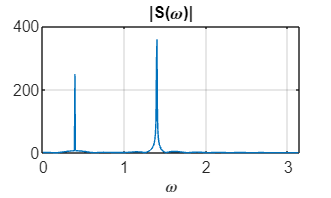

clf
% SU CÓDIGO AQUÍ
N = 512;
L = 1000;
n = (0:L-1)';
w = linspace(0, pi-pi/N, N);
s = cos(4*pi/9*n+pi/6)+1/2*cos(pi/8*n);
S = sum(s.*exp(-1j*n*w));
plot(w, abs(S))
% --------------
xlabel('\omega'), title('|S(\omega)|'), grid on
axis([0, pi, 0, 400])

check_task(144, 'es');

>>>>> [1:4:4] Correcto.


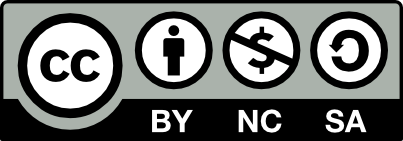 Práctica 1 © 2024 por José Parera licenciada bajo [CC BY-NC-SA 4.0](https://creativecommons.org/licenses/by-nc-sa/4.0/?ref=chooser-v1)